clear; clc; clf; close all;
load('./training-data/filtered_QHD_table.mat')
load('./training-data/filtered_QDP_table.mat')
load('./training-data/deleted_QHD_table.mat')
load('./training-data/deleted_QDP_table.mat')

QH = [filtered_QHD_table.FlowRate_m3h,filtered_QHD_table.Head_m]';
D  = [filtered_QHD_table.Diameter_mm]';

QH_beps=[deleted_QHD_table.FlowRate_m3h,deleted_QHD_table.Head_m]';
D_beps=[deleted_QHD_table.Diameter_mm]';

QD = [filtered_QDP_table.FlowRate_m3h,filtered_QDP_table.Diameter_mm]';
P = [filtered_QDP_table.Power_kW]';

QD_beps=[deleted_QDP_table.FlowRate_m3h,deleted_QDP_table.Diameter_mm]';
P_beps=[deleted_QDP_table.Power_kW]';

randomSeed = 4826;
nn_QHD_size_matrix = [5, 15];
nn_QDH_size_matrix = [5, 15];
nn_QDP_size_matrix = [2, 7, 29, 17];
maxEpochs = 355;
trainFcn = 'trainlm';

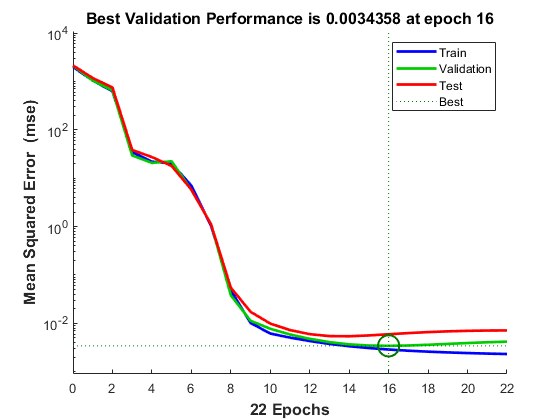

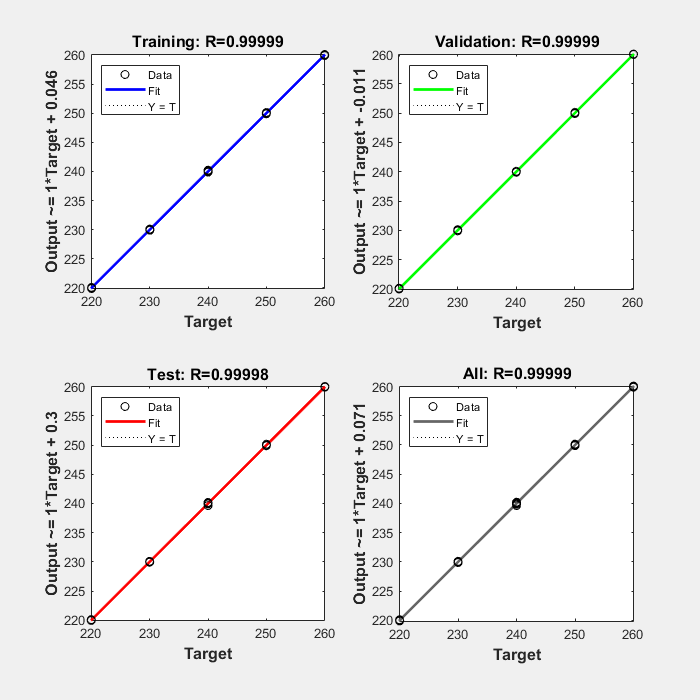

[trainedNetQHD, avgMSEsQHD, trainPerformanceQHD, valPerformanceQHD, testPerformanceQHD] = train_nn(nn_QHD_size_matrix, maxEpochs, trainFcn, QH, D, randomSeed);

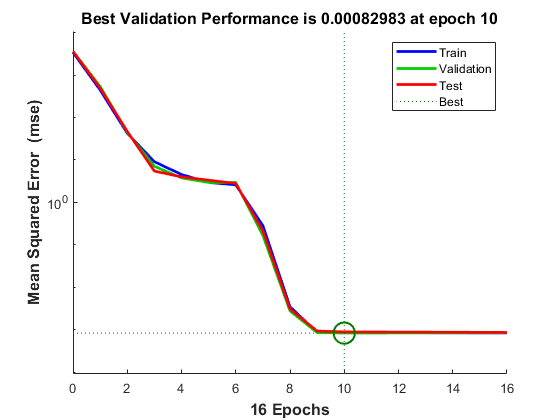

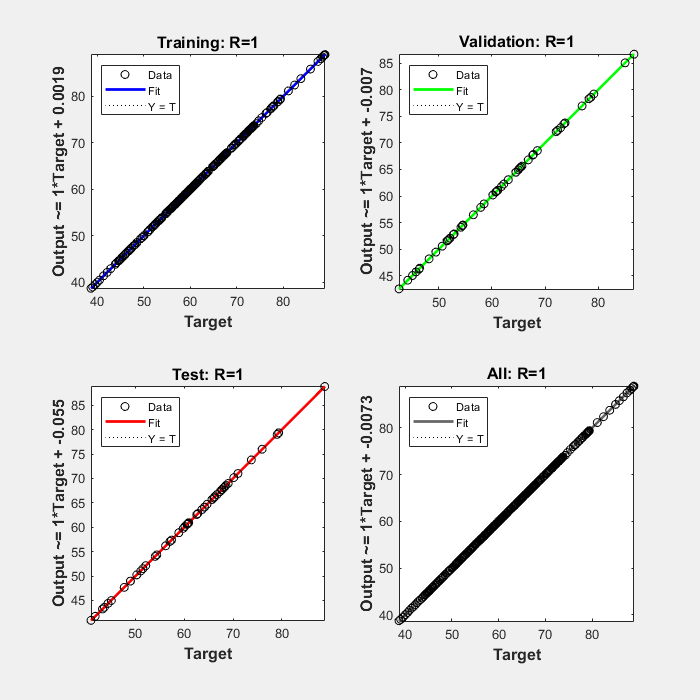

[trainedNetQDH, avgMSEsQDH, trainPerformanceQDH, valPerformanceQDH, testPerformanceQDH] = train_nn(nn_QDH_size_matrix, maxEpochs, trainFcn, [QH(1,:); D], QH(2,:), randomSeed);

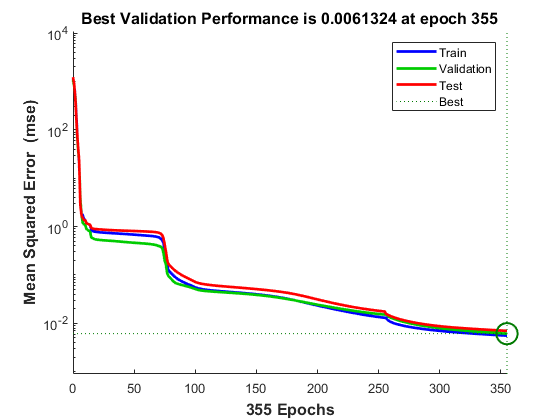

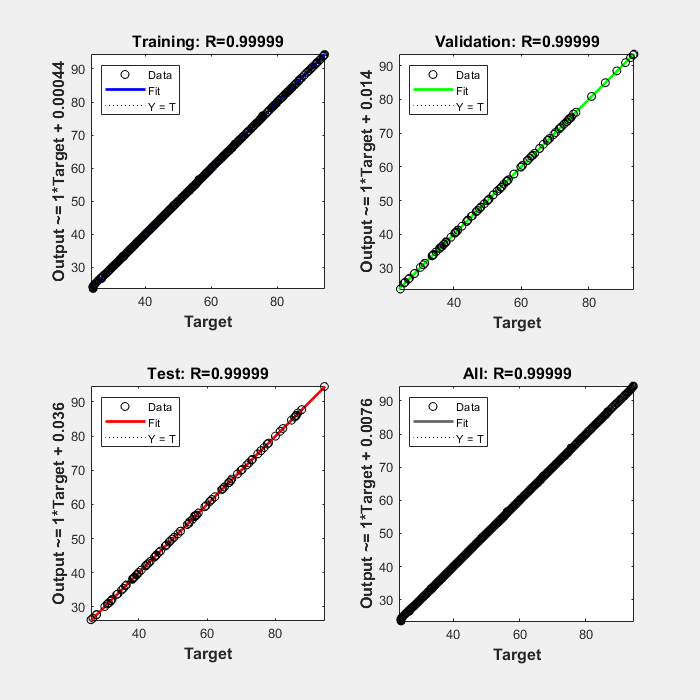

[trainedNetQDP, avgMSEsQDP, trainPerformanceQDP, valPerformanceQDP, testPerformanceQDP] = train_nn(nn_QDP_size_matrix, maxEpochs, trainFcn, QD, P, randomSeed);


distinctDiameters = unique(D);

% Extract the Q, H and D is already there in D.
Q = QH(1,:);
H = QH(2,:);

% Create a structure to hold Q,H curves for each diameter in unique_D.
pump_data = struct('Diameter', cell(length(distinctDiameters), 1), 'Q', cell(length(distinctDiameters), 1), 'H', cell(length(distinctDiameters), 1));

for i = 1:length(distinctDiameters)
    idx = (D == distinctDiameters(i));
    pump_data(i).Diameter = distinctDiameters(i);
    pump_data(i).Q = Q(idx);
    pump_data(i).H = H(idx);
end

% Initialize arrays to store errors and diameter reductions
percent_errors_cas_260 = zeros(1, 5);
percent_errors_cas_nearest = zeros(1, 5);
percent_errors_nn = zeros(1, 5);
percent_reductions = zeros(1, 5);


% Loop through each column in QH_beps
for i = 1:5
    d_real = D_beps(1, i); % Extracting d_real from D_beps

    % Calculate d using constant_area_scaling
    d_trimmed_cas_260 = constant_area_scaling(QH_beps(1, i), QH_beps(2, i), pump_data(5).Q, pump_data(5).H, pump_data(5).Diameter, 4);
    percent_errors_cas_260(i) = abs((d_trimmed_cas_260 - d_real) / d_real) * 100;

    % Calculate d using trim_diameters
    [d_trimmed_cas_nearest,d_ref] = trim_diameters(QH_beps(:, i), './training-data/filtered_QHD_table.mat');
    percent_errors_cas_nearest(i) = abs((d_trimmed_cas_nearest - d_real) / d_real) * 100;


    % Calculate d using trainedNetQHD
    d_trimmed_nn = bestNetQHD.net(QH_beps(:, i));
    percent_errors_nn(i) = abs((d_trimmed_nn - d_real) / d_real) * 100;


end

Error using trim_diameters
Too many output arguments.

constant_area_scaling(QH_beps(1, 4), QH_beps(2,4), pump_data(5).H,pump_data(5).Q,  pump_data(5).Diameter, 4)

ans = 238.8932

function D2_prime = constant_area_scaling(Q_prime, H_prime, H_curve, Q_curve, D2, poly_degree)
    % Center and scale the data
    Q_mean = mean(Q_curve);
    Q_std = std(Q_curve);
    H_mean = mean(H_curve);
    H_std = std(H_curve);
    Q_scaled = (Q_curve - Q_mean) / Q_std;
    H_scaled = (H_curve - H_mean) / H_std;
    
    % Fit the polynomial
    p = polyfit(Q_scaled, H_scaled, poly_degree);
    
    % Calculate the scaled A value
    A = H_prime / (Q_prime)^2;

    syms Q
    poly_expr = poly2sym(p, Q);
    
    eqn = A * Q^2 == poly_expr;
    sol = double(solve(eqn, Q));
    
    Q_valid = sol(sol > 0 & imag(sol) == 0 & sol <= max(Q_scaled) & sol >= min(Q_scaled));
    if isempty(Q_valid)
        error('No valid intersection found within the range of the pump curve.');
    end
    Q_intersect = max(Q_valid);
    
    % Scale back the Q_intersect value
    Q_intersect = Q_intersect * Q_std + Q_mean;

    D2_prime = Q_prime / Q_intersect * D2;
end
function [trainedNet, avgMSEs, trainPerformance, valPerformance, testPerformance] = train_nn(nn_size_matrix, maxEpochs, trainFcn, x, t, randomSeed)
    rng(randomSeed); % Set random seed for reproducibility.
    % Define the neural network.
    net = feedforwardnet(nn_size_matrix, trainFcn);
    % Suppress training GUI for efficiency.
    net.trainParam.showWindow = false;
    net.trainParam.epochs = maxEpochs;

    % Choose a Performance Function
    net.performFcn = 'mse';

    % Choose Input and Output Pre/Post-Processing Functions
    net.input.processFcns = {'removeconstantrows', 'mapminmax'};
    net.output.processFcns = {'removeconstantrows', 'mapminmax'};

    % Define data split for training, validation, and testing.
    % For a list of all data division functions type: help nndivide
    net.divideFcn = 'dividerand';  % Divide data randomly
    net.divideMode = 'sample';  % Divide up every sample
    net.divideParam.trainRatio = 0.7;
    net.divideParam.valRatio = 0.15;
    net.divideParam.testRatio = 0.15;

    % Train the neural network.
    [trainedNet, tr] = train(net, x, t);

    % Evaluate the model performance using mean squared error (MSE).
    predictions = trainedNet(x);
    mse = perform(trainedNet, t, predictions);

    % Recalculate Training, Validation and Test Performance
    trainTargets = t(tr.trainInd);
    valTargets = t(tr.valInd);
    testTargets = t(tr.testInd);
    trainPerformance = perform(trainedNet, trainTargets, predictions(tr.trainInd));
    valPerformance = perform(trainedNet, valTargets, predictions(tr.valInd));
    testPerformance = perform(trainedNet, testTargets, predictions(tr.testInd));

    % Calculate the average MSE
    avgMSEs = (mse + trainPerformance + valPerformance + testPerformance) / 4;

    % Plot the performance plot
    figure;
    plotperform(tr);

    % Plot the regression plots for training, validation, and test sets
    figure;
    plotregression(trainTargets, predictions(tr.trainInd), 'Training', ...
                   valTargets, predictions(tr.valInd), 'Validation', ...
                   testTargets, predictions(tr.testInd), 'Test', ...
                   t, predictions, 'All');

end
